# Perceptron: Or problem

### Algorithm

clear all ;close all
W = rand(4, 3)

W =     0.8147    0.6324    0.9575
    0.9058    0.0975    0.9649
    0.1270    0.2785    0.1576
    0.9134    0.5469    0.9706


X = [0 0; 0 1; 1 0 ; 1 1]

X =      0     0
     0     1
     1     0
     1     1


X = [ones(size(X,1), 1), X]

X =      1     0     0
     1     0     1
     1     1     0
     1     1     1


y = [-1, 1, 1, 1]

y =     -1     1     1     1


n_examples = size(X, 1);

converge = false;

while ~converge
    for i=1:n_examples
        y_est = hardlims(W(i,:) * X(i,:)')   
        error = y(i) - y_est
        W(mod(i, n_examples) + 1,:) = W(i,:) + error * X(i, :)
        
    end
    allRowsEqual = size(unique(W,'rows'),1)==1;
    if allRowsEqual
        converge = true;
    end
    
    slope = -(W(1,3)/W(1,2))
    intercept = -W(1,1)/W(1,2)
    xx = linspace(-1,1,100);
    yy = (slope * xx) + intercept
    hold on
    plot(xx, yy)
    plot([0 1 1], [1 1 0], 'xb')
    plot(0, 0, 'or')
    drawnow()    
end

y_est = 1

error = -2

W =     0.8147    0.6324    0.9575
   -1.1853    0.6324    0.9575
    0.1270    0.2785    0.1576
    0.9134    0.5469    0.9706


y_est = -1

error = 2

W =     0.8147    0.6324    0.9575
   -1.1853    0.6324    0.9575
    0.8147    0.6324    2.9575
    0.9134    0.5469    0.9706


y_est = 1

error = 0

W =     0.8147    0.6324    0.9575
   -1.1853    0.6324    0.9575
    0.8147    0.6324    2.9575
    0.8147    0.6324    2.9575


y_est = 1

error = 0

W =     0.8147    0.6324    2.9575
   -1.1853    0.6324    0.9575
    0.8147    0.6324    2.9575
    0.8147    0.6324    2.9575


slope = -4.6769

intercept = -1.2884

yy =     3.3886    3.2941    3.1996    3.1051    3.0106    2.9161    2.8217    2.7272    2.6327    2.5382    2.4437    2.3492    2.2547    2.1603    2.0658    1.9713    1.8768    1.7823    1.6878    1.5934    1.4989    1.4044    1.3099    1.2154    1.1209    1.0265    0.9320    0.8375    0.7430    0.6485    0.5540    0.4596    0.3651    0.2706    0.1761    0.0816   -0.0129   -0.1073   -0.2018   -0.2963   -0.3908   -0.4853   -0.5798   -0.6742   -0.7687   -0.8632   -0.9577   -1.0522   -1.1467   -1.2411


y_est = 1

error = -2

W =     0.8147    0.6324    2.9575
   -1.1853    0.6324    2.9575
    0.8147    0.6324    2.9575
    0.8147    0.6324    2.9575


y_est = 1

error = 0

W =     0.8147    0.6324    2.9575
   -1.1853    0.6324    2.9575
   -1.1853    0.6324    2.9575
    0.8147    0.6324    2.9575


y_est = -1

error = 2

W =     0.8147    0.6324    2.9575
   -1.1853    0.6324    2.9575
   -1.1853    0.6324    2.9575
    0.8147    2.6324    2.9575


y_est = 1

error = 0

W =     0.8147    2.6324    2.9575
   -1.1853    0.6324    2.9575
   -1.1853    0.6324    2.9575
    0.8147    2.6324    2.9575


slope = -1.1235

intercept = -0.3095

yy =     0.8140    0.7913    0.7686    0.7459    0.7232    0.7005    0.6778    0.6551    0.6324    0.6097    0.5870    0.5643    0.5416    0.5190    0.4963    0.4736    0.4509    0.4282    0.4055    0.3828    0.3601    0.3374    0.3147    0.2920    0.2693    0.2466    0.2239    0.2012    0.1785    0.1558    0.1331    0.1104    0.0877    0.0650    0.0423    0.0196   -0.0031   -0.0258   -0.0485   -0.0712   -0.0939   -0.1166   -0.1393   -0.1620   -0.1847   -0.2074   -0.2301   -0.2528   -0.2755   -0.2982


y_est = 1

error = -2

W =     0.8147    2.6324    2.9575
   -1.1853    2.6324    2.9575
   -1.1853    0.6324    2.9575
    0.8147    2.6324    2.9575


y_est = 1

error = 0

W =     0.8147    2.6324    2.9575
   -1.1853    2.6324    2.9575
   -1.1853    2.6324    2.9575
    0.8147    2.6324    2.9575


y_est = 1

error = 0

W =     0.8147    2.6324    2.9575
   -1.1853    2.6324    2.9575
   -1.1853    2.6324    2.9575
   -1.1853    2.6324    2.9575


y_est = 1

error = 0

W =    -1.1853    2.6324    2.9575
   -1.1853    2.6324    2.9575
   -1.1853    2.6324    2.9575
   -1.1853    2.6324    2.9575


slope = -1.1235

intercept = 0.4503

yy =     1.5738    1.5511    1.5284    1.5057    1.4830    1.4603    1.4376    1.4149    1.3922    1.3695    1.3468    1.3241    1.3014    1.2787    1.2560    1.2333    1.2106    1.1879    1.1652    1.1425    1.1198    1.0971    1.0744    1.0518    1.0291    1.0064    0.9837    0.9610    0.9383    0.9156    0.8929    0.8702    0.8475    0.8248    0.8021    0.7794    0.7567    0.7340    0.7113    0.6886    0.6659    0.6432    0.6205    0.5978    0.5751    0.5524    0.5297    0.5070    0.4843    0.4616


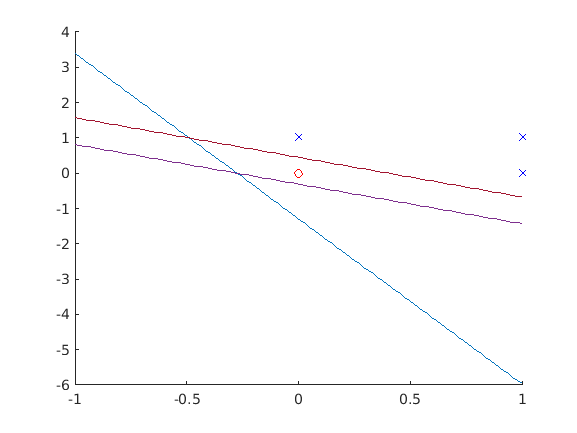

    hold off

### Plot Decision Boundary

slope = -(W(1,3)/W(1,2))

slope = -0.7541

intercept = -W(1,1)/W(1,2)

intercept = 0.5979

xx = linspace(-1,1,100);

% y = mx+b
y = (slope * xx) + intercept

y =     1.3519    1.3367    1.3215    1.3062    1.2910    1.2758    1.2605    1.2453    1.2301    1.2148    1.1996    1.1844    1.1691    1.1539    1.1387    1.1234    1.1082    1.0930    1.0777    1.0625    1.0473    1.0320    1.0168    1.0016    0.9863    0.9711    0.9559    0.9406    0.9254    0.9102    0.8949    0.8797    0.8645    0.8492    0.8340    0.8188    0.8035    0.7883    0.7731    0.7578    0.7426    0.7274    0.7121    0.6969    0.6817    0.6664    0.6512    0.6360    0.6207    0.6055


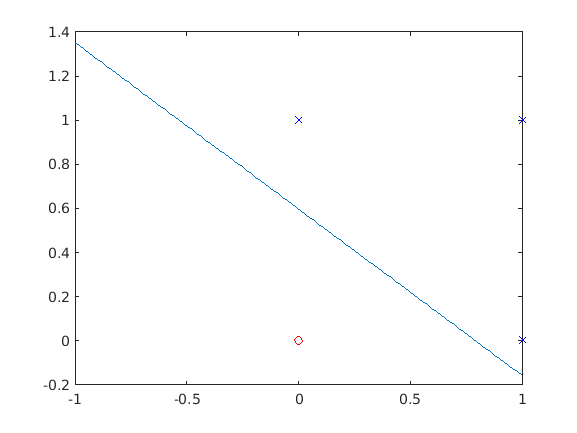

figure,
plot(xx, yy);hold on
plot([0 1 1], [1 1 0], 'xb')
plot(0, 0, 'or')
hold off